# 期末总复习第一题

## 第一题第5问：

clear;
num=[2 -2.9];         %设定函数的分子向量
den = [1 -2.9 1];   %设定函数的分母向量
%disp(roots(num));    %输出零点
%disp(roots(den));    %输出极点
[Z P K]=tf2zp(num,den);
fprintf('零点：\n');

零点：


disp(Z);

    1.4500



fprintf('极点：\n');

极点：


disp(P);

    2.5000
    0.4000



fprintf('增益： %.2f\n',K);

增益： 2.00


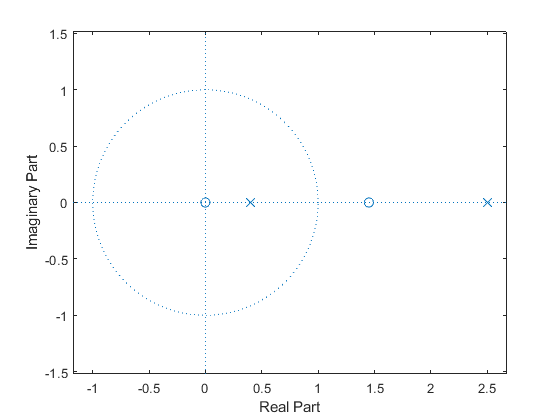

zplane(num,den);   %绘制系统函数的零极点图

## 第一题第7问：

clear all;
close all;
% 给定 IIR滤波器；
H1=[2 -2.9];         %设定函数的分子向量
H2=[1 -2.9 2];   %设定函数的分母向量

k1=tf2latc(H1)      % 求H1的lattice系数

k1 = -1.4500

k2=tf2latc(H2)      % 求H2的lattice系数

k2 =    -0.9667
    2.0000


%[k1,v1]=tf2latc(H1,1);      % 求H1的lattice系数
%[k2,v2]=tf2latc(H2,1);      % 求H2的lattice系数
[k3,c]=tf2latc(H1,H2)        % 求H3的lattice系数

k3 =    -0.9667
    2.0000


c =    -0.8033
   -2.9000
         0
